K = [-1.5 0 0.2 0 0.4 0;      %the obtained rate of reacion matrix
    0.3 -1 0.4 0 0.6 0; 
    0 0.4 -2.1 0.4 0 0.02; 
    0 0 0.9 -0.41 0.2 0; 
    0.4 0.6 0 0.01 -2 0; 
    0.8 0 0.6 0 0.8 -0.02];
[EV,ev] = eig(K); %Eigen Vectors and values
%Formulating the general soln
syms c1 c2 c3 c4 c5 c6 t 
y = c1*EV(:,1)*exp(ev(1,1)*t) + c2*EV(:,2)*exp(ev(2,2)*t) + c3*EV(:,3)*exp(ev(3,3)*t) + c4*EV(:,4)*exp(ev(4,4)*t) + c5*EV(:,5)*exp(ev(5,5)*t) + c6*EV(:,6)*exp(ev(6,6)*t);
%substituting the initial conditions
eqn1 = subs(y(1),t,0) == 1;
eqn2 = subs(y(2),t,0) == 0;
eqn3 = subs(y(3),t,0) == 0;
eqn4 = subs(y(4),t,0) == 0;
eqn5 = subs(y(5),t,0) == 0;
eqn6 = subs(y(6),t,0) == 0;
%solving the finalized equations for the constant values 
sol = solve([eqn1,eqn2,eqn3,eqn4,eqn5,eqn6],[c1,c2,c3,c4,c5,c6]);
%substituting the constant values 
% in the general soln for particualar soln
y = subs(y,[c1,c2,c3,c4,c5,c6],[sol.c1,sol.c2,sol.c3,sol.c4,sol.c5,sol.c6]);
disp(y)

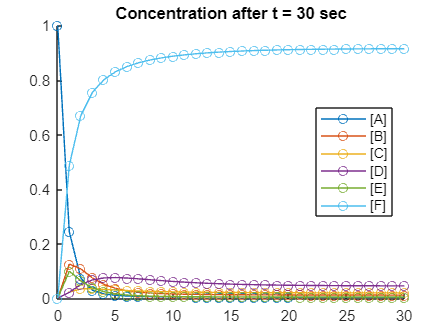

%plotting our particular solution
hold on
%fplot(y,[0,30],"-")
%checking its accuracy against output from the ode45() solver by plotting
%both of them together on the same frame
y0 = [1 0 0 0 0 0]';  %Initial conditions
tspan = 0:1:30;  %time span
[x,y] = ode45(@odesystem,tspan,y0);
plot(x,y,"-o")
hold off
lgd = legend("[A]","[B]","[C]","[D]","[E]","[F]");
lgd.Location = "east";
title("Concentration after t = 30 sec")